# Rigid Body Project

## Team # 0Rigid Body Project

## Team # 02

## Team Members:

Jacob Juers

Dennis Pomazanov

Christopher Barnes

## Problem Statement

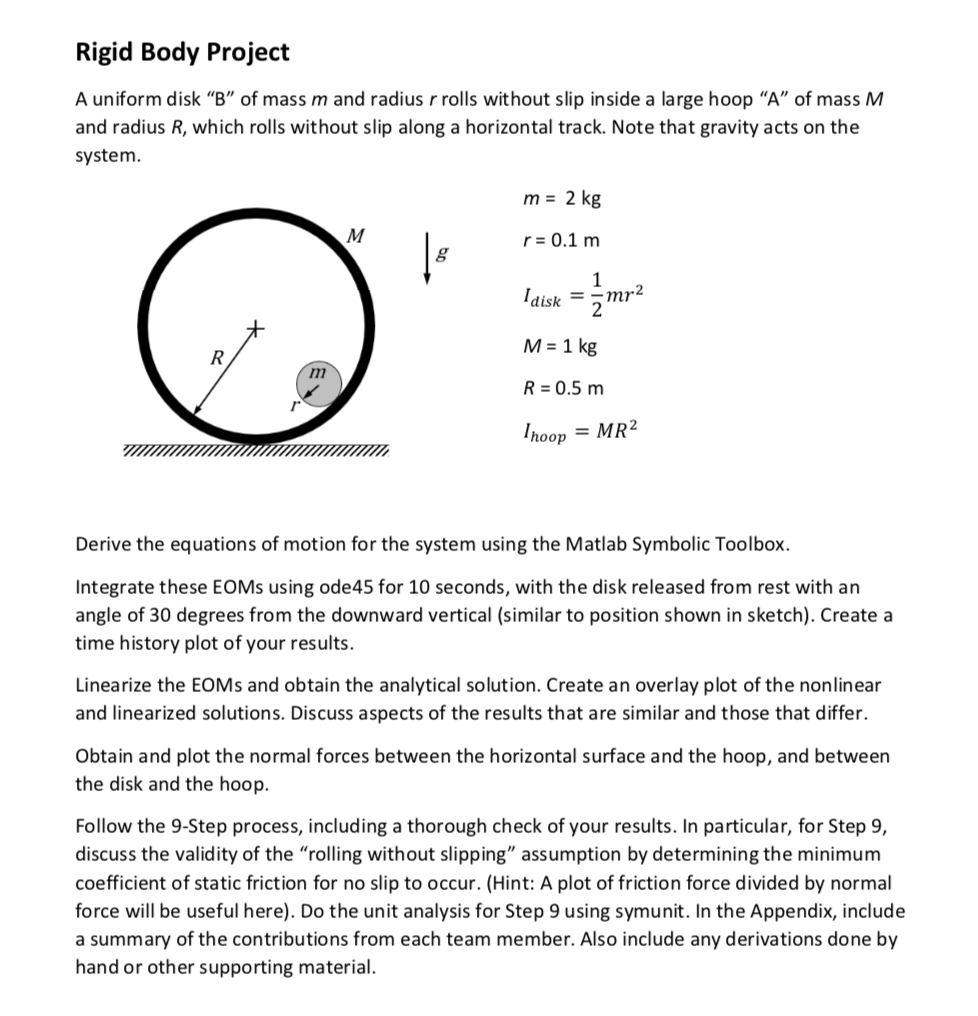

## Step 1: Conceptualize the Problem

Find equations of motion and use them to solve.

- 2 degrees of freedom,  $x_H$(Horizontal displacement of hoop), $\phi$*(*Angle of displacement from the vertical of disk) 

- Disk translates in tangential direction relative to the center of the hoop and rotates around its center

- Hoop translates only in the x-direction and rotates about its center

- Assume no-slip condition

- Assume rigid body dynamics

## Step 2: Coordinate System

For the hoop, align the x-axis parallel the the horizontal track with the y-axis normal to the horizontal track. For the disk, align the normal direction through the two centers of masses of the hoop and the disk and the tangential direction normal to this. 

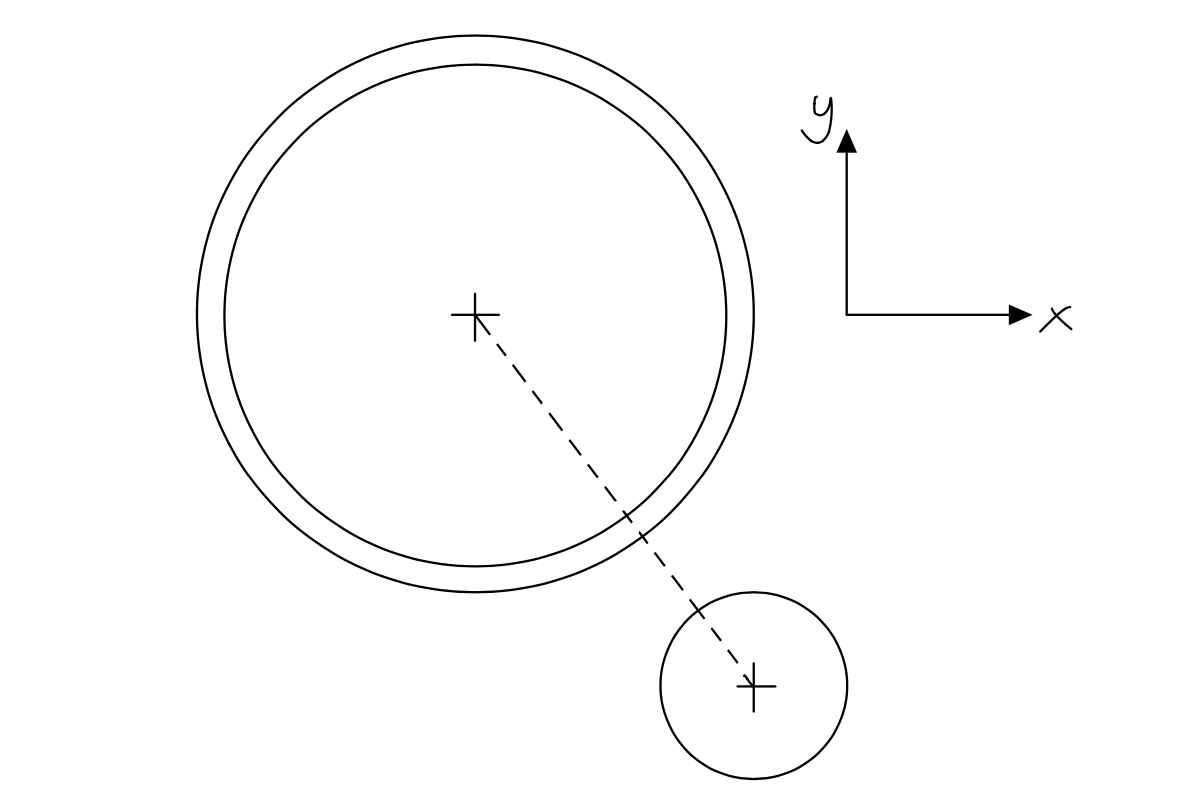

## Step 3: FBD

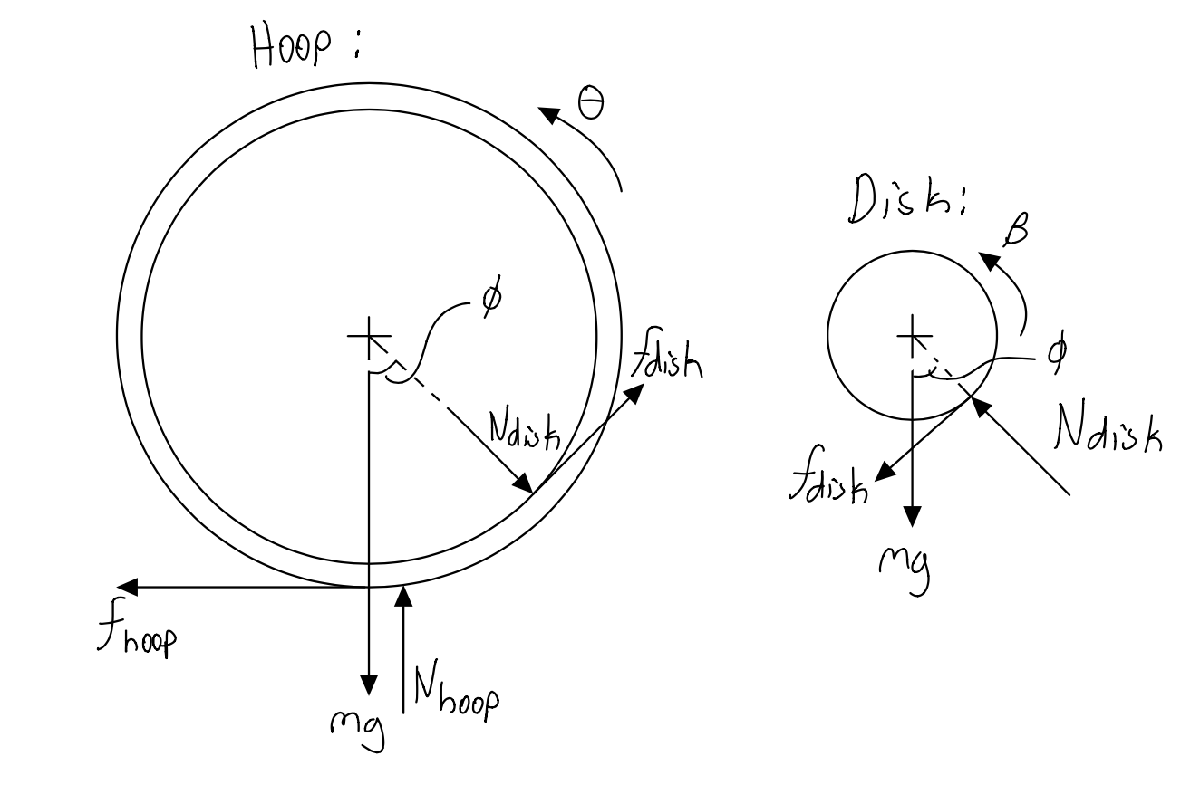

## Step 4: Fundemental Equations


$$\Sigma F=\textrm{ma}$$



$$\Sigma M_{\textrm{cm}} =I_{z_{\textrm{cm}} } \theta^¨$$


fh =  Force of friction between hoop and ground

fd =  Force of friction between disk and hoop 

Nd =Normal force between disk and hoop 

Nh =Normal force between hoop and ground

clear
clc
syms fh fd Nd Nh theta thetadot thetaddot xH xdotH xddotH xddotD yddotD yddotH  phiddot phidot ...
    beta betadot betaddot m g R r M IHz IDz phi

## Hoop:

#### **Sum in x-direction**

Sum of forces acting on the hoop in the horizontal direction is equal to the mass of the hoop times the horizontal acceleration of the hoop is equal to the force of friction 

between the hoop and the ground plus the normal force acting between the disk and the hoop times sin(angular displacement of the disk) minus the force of fr`i`ction 

between the disk and the hoop times cos(angular displacement of the disk). 

eqn(1) = M*xddotH == fh + Nd*sin(phi) - fd*cos(phi);

**Sum in y-direction**

Sum of forces acting on the hoop in the vertical direction is equal to the mass of the hoop times the vertical acceleration of the hoop is equal to the weight of the hoop plus 

the normal force between the hoop and the ground minus the normal force between the disk and the hoop times cos(angular displacement of the disk) minus the force of 

friction between the disk and the hoop times sin(angular displacement of the disk). 

eqn(2) = M*yddotH == -M*g + Nh - Nd*cos(phi) - fd*sin(phi); 

**Sum of Moments**

The sum of moments on the hoop about the center of mass equals the moment of inertia of the hoop (MR^2) about the center of mass times the angular acceleration of the hoop equals the force of friction between the hoop and the ground times the radius of the hoop minus the force of friction between the disk and the hoop times the radius of the hoop`. `

eqn(3) = IHz*thetaddot == fh*R - fd*R;

## Disk:

#### Sum in Tangential direction

Sum of forces acting on the disk in the horizontal direction is equal to the mass of the disk times the horizontal acceleration of the disk is equal to force the friction between the disk and the hoop times the cos(angular displacement of the disk) minus the normal force between the disk and the hoop times the sin(angular displacement of the disk). 

eqn(4) =  m*xddotD == fd*cos(phi)-Nd*sin(phi);

**Sum in Normal direction**

Sum of forces acting on the disk in the vertical direction is equal to the mass of the disk times the vertical acceleration of the disk is equal to the negative of the mass of the disk times gravity plus the force of friction between the disk and hoop times the sin(angular displacement of the disk) plus the normal force between the disk and hoop times the cos(angular displacement of the disk). 

eqn(5) = m*yddotD == -m*g+fd*sin(phi) + Nd*cos(phi);

**Sum of Moments**

The sum of moments acting on the disk is equal to the moment of inertia of the disk times the angular acceleration of the disk is equal to the force of friction between the 

disk and the hoop times the radius of the disk. 

eqn(6) = IDz*betaddot == r*fd;

**Inertia of hoop and disk** eqn 7 and 8


$$\;I_H =MR^2$$


eqn(7) = IHz == M*R^2;


$$I_D =\frac{1}{2}mr^2$$


eqn(8) = IDz == (1/2)*m*r^2; 

## Step 5: Knowns and Unknowns

## Knowns

$\theta$ (angle from downward vertical)

m (mass of disk, 2kg)

g (acceleration due to gravity, $9\ldotp 8\;\frac{m}{s^2 }$)

M (mass of hoop, 1kg)

r (radius of disk, 0.1m)

R (radius of hoop, 0.5m)

$x$ (system position state variable)

$\dot{x}$ (system velocity state variable)

$\theta^˙$ (system angular velocity state variable)

$\phi$ (hoop angular postition state variable)

$\phi^˙$ (hoop angular velocity state variable)

$\beta$ (disk angular position state variable)

$\beta^˙$ (disk angular velocity state variable)

## Unknowns

$f_h$ (friction force on hoop)

$f_d$ (friction force on disk)

$N_h$ (normal force of hoop)

$N_d$ (normal force of disk)

$\ddot{x}$ h(acceleration in the x-direction for hoop) -EOM

$\ddot{x}$ d(acceleration in the x-direction for disk)

$\ddot{y_D }$(acceleration in the y direction of disk)

$\theta^¨$ (angular acceleration of the system)

$\phi^¨$ (angular acceleration of the hoop)

$\beta^¨$ (angular acceleration of the disk) - EOM

## 8 equations, 10 unknowns

## Step 6: Constrants 

**Rolling without slipping - Hoop and Ground : **

The relative velocity of the Hoop and the Ground at their contact point is equal to 0.

Relates${\overset{\cdot \cdot }{x} }_H \;\textrm{to}\;\theta^{\cdot \cdot }$


$${\overset{\rightharpoonup }{v} }_H ={\overset{\rightharpoonup }{v} }_o +{\omega^{\rightharpoonup } }_{\theta } \times {\overset{\rightharpoonup }{r} }_{H/0}$$



$$\left\lbrack \begin{array}{c}
{\overset{\cdot }{x} }_H \\
{\overset{\cdot }{y} }_H 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
x & y & z\\
0 & 0 & \theta^{\cdot } \\
0 & R & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-R\theta^{\cdot } \\
0
\end{array}\right\rbrack$$



$${\overset{\cdot \cdot }{x} }_H =$$

$$\;-R\theta^{\cdot }$$


eqn(9) = xddotH == -R*thetaddot;

**Rolling without Slipping - Disk and Hoop : **

Relates$\;\beta^{\cdot \cdot } ,\;\overset{\cdot \cdot }{\theta ,} \textrm{and}\;\phi^{\cdot \cdot }$


$${\overset{\rightharpoonup }{v} }_P ={\overset{\rightharpoonup }{v} }_H +{\omega^{\rightharpoonup } }_{\theta } \times {\overset{\rightharpoonup }{r} }_{P/H} ={\overset{\rightharpoonup }{v} }_D +{\omega^{\rightharpoonup } }_{\beta } \times {\overset{\rightharpoonup }{r} }_{P/D} \;$$



$${\overset{\rightharpoonup }{v} }_D ={\overset{\rightharpoonup }{v} }_H +{\omega^{\rightharpoonup } }_{\theta } \times {\overset{\rightharpoonup }{r} }_{D/H}$$



$${\overset{\rightharpoonup }{v} }_H +{\omega^{\rightharpoonup } }_{\theta } \times {\overset{\rightharpoonup }{r} }_{P/H} ={\overset{\rightharpoonup }{v} }_H +{\omega^{\rightharpoonup } }_{\phi } \times {\overset{\rightharpoonup }{r} }_{D/H} +{\omega^{\rightharpoonup } }_{\beta } \times {\overset{\rightharpoonup }{r} }_{D/H} \;\;$$



$$\left\lbrack \begin{array}{ccc}
x & y & z\\
0 & 0 & \theta^{\cdot } \\
\textrm{Rsin}\phi  & -\textrm{Rcos}\phi  & 0
\end{array}\right\rbrack =\;\left\lbrack \begin{array}{ccc}
x & y & z\\
0 & 0 & \phi^{\cdot } \\
\left(R-r\right)\sin \phi  & -\left(R-r\right)\cos \phi  & 0
\end{array}\right\rbrack +\left\lbrack \begin{array}{ccc}
x & y & z\\
0 & 0 & \beta^{\cdot } \\
\textrm{rsin}\phi  & -\textrm{rcos}\phi  & 0
\end{array}\right\rbrack$$



$$R\theta^{\cdot } \left\lbrack \begin{array}{c}
\cos \phi \\
\sin \phi 
\end{array}\right\rbrack =\left(R-r\right)\phi \left\lbrack \begin{array}{c}
\cos \phi \\
\sin \phi 
\end{array}\right\rbrack +r\beta^{\cdot }$$



$$\;\theta^{\cdot \cdot } =\frac{\left(R-r\right)\;\phi^{\cdot \cdot } +r\beta^¨ }{R}$$


eqn(10) = thetaddot == ((R-r)*phiddot+r*betaddot)/R;

**Surfaceconstraint - Disk's path about Hoop's center:**

Relates$\;\overset{\cdot \cdot }{x_D } \;\textrm{to}\;\;\overset{\cdot \cdot }{\theta ,} \;\textrm{and}\;\phi^{\cdot \cdot }$

Relates $\;\overset{\cdot \cdot }{y_D } \;\textrm{to}\;\phi^{\cdot \cdot }$


$${\overset{\rightharpoonup }{v} }_D ={\overset{\rightharpoonup }{v} }_H +{\omega^{\rightharpoonup } }_{\phi } \times {\overset{\rightharpoonup }{r} }_{D/H}$$



$$\left\lbrack \begin{array}{c}
{\overset{\cdot }{x} }_D \\
{\overset{\cdot }{y} }_D 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-R\theta \\
0
\end{array}\right\rbrack +\left(R-r\right)\phi^{\cdot } \left\lbrack \begin{array}{c}
\cos \phi \\
\sin \phi 
\end{array}\right\rbrack$$



$${\overset{\cdot \cdot }{x} }_D =-R\theta^{\cdot \cdot } +\left(R-r\right)\phi^{\cdot \cdot } \cos \left(\phi \right)-\left(R-r\right)\overset{\cdot }{\phi^2 } \sin \phi$$


eqn(11) = xddotD == -R*thetaddot+(R-r)*phiddot*cos(phi)-(R-r)*phidot^2*sin(phi);


$${\overset{\cdot \cdot }{y} }_D =\left(R-r\right)\phi^{\cdot \cdot } \sin \left(\phi \right)+\left(R-r\right)\overset{\cdot }{\phi^2 } \cos \phi$$


eqn(12) = yddotD == (R-r)*phiddot*sin(phi)+(R-r)*phidot^2*cos(phi);

## Step 7: Obtain the EOMs

Solve the system of equation to fiind EOM $\overset{\cdot \cdot }{x}$ and $\phi^{\cdot \cdot }$

unknowns = solve(eqn,[betaddot,thetaddot,phiddot, xddotH,xddotD,yddotD, Nd, Nh, fh, fd, IHz,IDz]);
xddotHEOM = simplify(unknowns.xddotH)

$$xddotHEOM = \frac{m\,\left(g\,\sin\left(\varphi \right)+3\,R\,{\mathrm{phidot}}^{2}\,\sin\left(\varphi \right)+2\,g\,\cos\left(\varphi \right)\,\sin\left(\varphi \right)-3\,{\mathrm{phidot}}^{2}\,r\,\sin\left(\varphi \right)\right)}{-2\,m\,{\cos\left(\varphi \right)}^{2}-2\,m\,\cos\left(\varphi \right)+6\,M+4\,m}$$

phiddotEOM = simplify(unknowns.phiddot)

$$phiddotEOM = -\frac{3\,g\,m\,\sin\left(\varphi \right)+4\,M\,g\,\sin\left(\varphi \right)+R\,m\,{\mathrm{phidot}}^{2}\,\sin\left(2\,\varphi \right)-m\,{\mathrm{phidot}}^{2}\,r\,\sin\left(2\,\varphi \right)+R\,m\,{\mathrm{phidot}}^{2}\,\sin\left(\varphi \right)-m\,{\mathrm{phidot}}^{2}\,r\,\sin\left(\varphi \right)}{\left(R-r\right)\,\left(-2\,m\,{\cos\left(\varphi \right)}^{2}-2\,m\,\cos\left(\varphi \right)+6\,M+4\,m\right)}$$

**Solve Linearized EOMs:**

LinEOMs = expand(subs([unknowns.xddotH;unknowns.phiddot],...
    [str2sym('sin(phi)'),str2sym('cos(phi)'),str2sym('phidot^2')] ...
    ,[phi,1,0])); 
LinEOMs = subs(LinEOMs,str2sym('phi^2'),0);

Put int the form $\overset{\cdot \cdot }{x} =\left\lbrack \begin{array}{c}
A
\end{array}\right\rbrack \overset{\rightharpoonup }{x}$

factor out $\phi$

A = equationsToMatrix(LinEOMs,[xH,phi]);


$$\left\lbrack \begin{array}{c}
\overset{\cdot \cdot }{x_H } \\
\phi^{\cdot \cdot } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & \frac{\textrm{gm}}{2M}\\
0 & 3\frac{\textrm{gm}}{6M-6\textrm{MR}}-4\frac{\textrm{Mg}}{6\textrm{Mr}-6\textrm{MR}}
\end{array}\right\rbrack \phi$$


## Step 8: solve the equation(s) of motion, solve the problem 

**Solve non-Linear EOMS**

syms xH(t) xdotH(t) phi(t) phidot(t) 

Substitute these symbolic functions into the EOMs

accelEOMs = subs([xddotHEOM;phiddotEOM],[str2sym('phi'),str2sym('phidot')],[phi,phidot]);
eom = odeFunction([xdotH;phidot;accelEOMs],[xH;phi;xdotH;phidot],g,m,M,r,R);

Specify parameter values, integrate EOMs over 10 seconds:

gn = 9.81;              % gravitational constant, m/s^2
rn = 0.1;               %radius of disk, m
Rn = 0.5;               %radius of hoop,m
mn = 2;                 %mass, kg
Mn = 1;                 %mass, kg
IC(1) = 0;              %inertia x
IC(2) = deg2rad(30);    %initial theta
IC(3) = 0;              %initial of xdot
IC(4) = 0;              %initial thetadot
t0 = 0;                 %initial time
tf = 10;                %final time
ntime = 1001;           %number of time point
[T,S] = ode45(@(t,s)eom(t,s,gn,mn,Mn,rn,Rn),linspace(t0,tf,ntime),IC);

**Plot time history**:

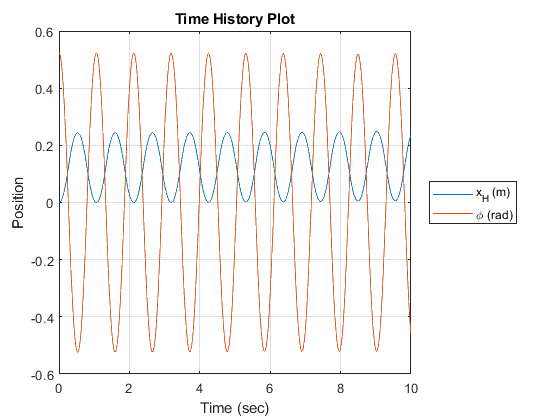

plot(T,S(:,1:2),'-')
title('Time History Plot')
xlabel('Time (sec)')
ylabel('Position')
legend('x_{H} (m)','\phi (rad)','Location','eastoutside')
grid on;

Here we can see that the initial starting position of the disk starts at 30 degrees from vertical (0.5236 radians) and as it drops due to gravity, the hoop rolls to the right in the positive x-direction a distance a little over 0.2m. The disk oscillates between positive and negative values of 0.5236 radians. At the point in which the hoop starts to roll back towards its initial starting position in the negative x-direction, the value of phi for the disk reaches a positve 0.5236 value. The point in which the disk starts to roll back towards the positive x-direction,phi approaches a negative value of -0.5236 radians. The Hoop oscillates just above the values of 0.2m and 0 due to the starting position of phi. If phi initial starting position was in the negative direction, then the hoop would oscillate between 0 and a value a little less than -2m. Since the friction force and the normal force between the disk and hoop are equal to and oposite of each rigid body, they will cancel out, and both the disk and hoop will oscillate between the t*w*o stated values in the positive and negative directions. At the end of the 10 seco`nd`s, the final positions of the disk and hoop are close to their initial starting positions with a slight deviation to the left for the disk and a slight deviation to the right for the hoop. 

## Solve Linearized EOMs:

Turn A into a number, double precision: 

An = eval(subs(A,[g,m,M,r,R],[gn,mn,Mn,rn,Rn]));

**Solve Eigenvalue/Eigenvector problem using "eig" function**:

[c,rsquared] = eig(An)

c =     1.0000   -0.2334
         0    0.9724


rsquared =          0         0
         0  -40.8750


omega = imag(sqrt([rsquared(1,1);rsquared(2,2)]));

**To solve for the coefficients use the initial conditions: **


$$\overset{\cdot \cdot }{x} \left(0\right)={\overset{-}{c} }_1 A+{\overset{-}{c} }_2 C=\left\lbrack \begin{array}{cc}
c_1  & c_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
A\\
C
\end{array}\right\rbrack =\left\lbrack C\right\rbrack \left\lbrack \begin{array}{c}
A\\
C
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
A\\
C
\end{array}\right\rbrack =\left\lbrack C^{-1} \right\rbrack \overset{-}{x} \left(0\right)$$


ACcoef = c^-1*IC(1:2)';

Since, $\overset{\rightharpoonup }{x} =\omega_1 {\overset{-}{c} }_1 \left(\left.-\textrm{Asin}\left(\omega_1 t\right)+\textrm{Bcos}\left(\omega_1 t\right)\right)+\omega_2 {\overset{-}{c} }_2 \left(-\textrm{Csin}\left(\omega_2 t\right)+\textrm{Dcos}\left(\omega_2 t\right)\right)\right)$


$$\overset{\rightharpoonup }{x} \left(0\right)=\omega_1 {\overset{-}{c} }_1 B+{\overset{-}{c} }_2 C=\omega_2 {\overset{-}{c} }_2 D=\left\lbrack C\right\rbrack \left\lbrack \begin{array}{c}
\omega_1 B\\
\omega_2 D
\end{array}\right\rbrack$$


BDcoef = c^-1*IC(3:4)';
x = c(:,1).*(ACcoef(1)*cos(omega(1)*T')+BDcoef(1)*sin(omega(1)*T'))+ ...
    c(:,2).*(ACcoef(2)*cos(omega(2)*T')+BDcoef(2)*sin(omega(2)*T')); % 2 rows by n columns

**Plot Linearized Solution Vs. Non - Linearized Solutions:**

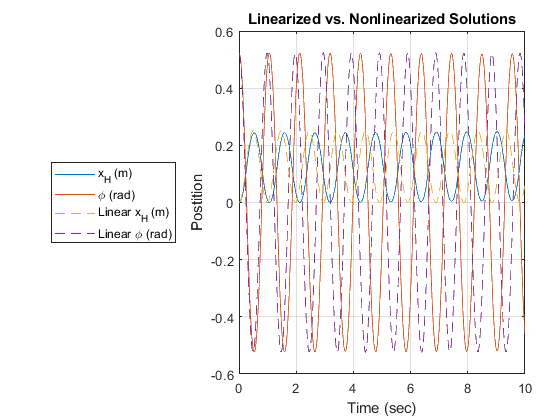

figure
plot(T,S(:,1:2),'-',T',x,'--')
title('Linearized vs. Nonlinearized Solutions')
xlabel('Time (sec)')
ylabel('Postition')
legend('x_{H} (m)','\phi (rad)','Linear x_{H} (m)','Linear \phi (rad)','Location','westoutside')
grid on;

Both the linearized and non-linearized solutions have very similiar values during the first second before they start to differ majorly. As time continues, this difference between the two solutions continues to grow in which the linearized solution deviates from the non-linearized solution. Both linearized solutions howe*v*er, oscillate betwen the same negative and positive values as the non-linearized solutions (0.5236 radians, <0.2m and Om). At the end of the 10 seconds, the final positions of the linea`r`ized soluions are nearly at the opposite point of their respective wavelengths in comparison to the non-linearized soulutions, despite having the same starting positions. The disk ends up on the nega`t`ive, or left of the vertical, side in the linearized solution whereas the disk results in the positive, right of the vertical, side in the non linearized solution. The hoop ends up close to its initial starting position after the 10 seconds in the non-linearized solution but ends up to the right a distance a little over  0.2 meters in the linearized solution. 

**Plotting of Normal Forces in the Hoop and Disk**

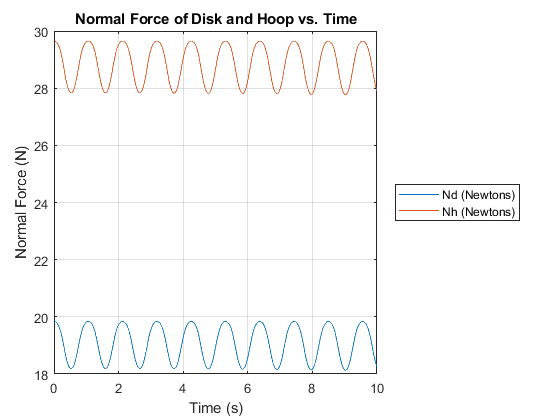

Norm_h = simplify(unknowns.Nh);
Norm_d = simplify(unknowns.Nd);

NormalEQ = subs([Norm_d;Norm_h],[str2sym('phi'),str2sym('phidot')],[phi,phidot]);
fNormal = odeFunction(NormalEQ,[phi;phidot],g,m,M,r,R,yddotH);
yddotHs = 0;
N_plot = fNormal(T,S',gn,mn,Mn,rn,Rn,yddotHs);
figure
plot(T,N_plot,'-')
title('Normal Force of Disk and Hoop vs. Time')
xlabel('Time (s)')
ylabel('Normal Force (N)')
legend('Nd (Newtons)','Nh (Newtons)','Location','eastoutside')
grid on;

Looking at the plot of the normal force on the hoop as well as the normal force on the disk is very depictive of the motion we have for this probelm. First of all, the normal force for the hoop is larger because it accounts for both the weight of the disk and the hoop combined. The normal force for the disk is much smaller becasue this only accounts for the weight of the disk. Also, the sinosoidal pattern of both of these lines makes sense as well. As the disk rolls back and forth in the hoop, the components of normal force, friction, and weight are always changing. For instance, when the disk reaches the bottom of the hoop, there is no friction force component and all of the weight is acting in the downward direction making this the point where the maximum normal force occurs. In other words, the weights of both objects as well as the normal foces are both aligned vertically at this point. In contrast, when the disk reahes the maximim height off of the ground, we have the different components of weight as well as the friction force so this is where the normal force will be the lowest.

## Step 9: Does it Make Sense? 

**Rolling Without Slipping Condition**

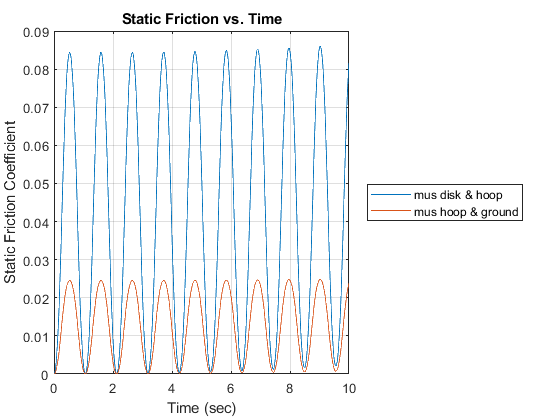

mu_static = odeFunction([unknowns.fd/unknowns.Nd, unknowns.fh/unknowns.Nh],[phi,phidot],g,m,M,r,R,yddotH);
mu_plot = mu_static(T, S',gn,mn,Mn,rn,Rn,yddotHs);
figure
plot(T,abs(mu_plot),'-')
title('Static Friction vs. Time')
xlabel('Time (sec)')
ylabel('Static Friction Coefficient')
legend('mus disk & hoop','mus hoop & ground','Location','eastoutside')
grid on;

The coefficient of static friction needed for the rolling without slipping condition to occur between the disk and the hoop is a much higher value than the coefficient of static friction between the hoop and the ground (just over 4 times as much as indicated by the graph). T`h`e reasoning for this involves the fact that between the hoop and disk there exists friction between two moving objects moving in opposite directions as compared to a moving object between a stationary object (the ground). At the points where the coefficient of static friction is minimum (equal to 0) the translational velocities and the rotational velocities of the system are also 0, making the rolling without slipping condition valid. If there was kinetic friction there would be slipping at one or more of the contact points and it would cause energy loss which would lead to a dampening effect in our equations of motion. 

**Units Check**

u = symunit;
Variables.fh = fh*u.N;
Variables.fd = fd*u.N;
Variables.Nd = Nd*u.N;
Variables.Nh = Nh*u.N;
Variables.thetadot = thetadot/u.s;
Variables.thetaddot = thetaddot/u.s^2;
Variables.xH = xH*u.m;
Variables.xdotH = xdotH*u.m/u.s^2;
Variables.xddotH = xddotH*u.m/u.s^2;
Variables.xddotD = xddotD*u.m/u.s^2;
Variables.yddotD = yddotD*u.m/u.s^2;
Variables.yddotH = yddotH*u.m/u.s^2;
Variables.phiddot = phiddot/u.s^2;
Variables.phidot = phidot/u.s;
Variables.betadot = betadot/u.s;
Variables.betaddot = betaddot/u.s^2;
Variables.m = m*u.kg;
Variables.g = g*u.m/u.s^2;
Variables.R = R*u.m;
Variables.r = r*u.m;
Variables.M = M*u.kg;
Variables.IHz = IHz*u.kg*u.m^2;
Variables.IDz = IDz*u.kg*u.m^2;
eqnUnits = subs(eqn,Variables);
checkUnits(eqnUnits)

ans = struct with fields:
    Consistent: [1 1 1 1 1 1 1 1 1 1 1 1]
    Compatible: [1 1 1 1 1 1 1 1 1 1 1 1]


Checking EOMs:

phiddotEOMunits = subs(phiddotEOM,Variables);
[~,phiddotEOMunits] = separateUnits(phiddotEOMunits);
phiddotEOMunits

$$phiddotEOMunits = \frac{1}{s^{2}}$$

xddotHEOMunits = subs(xddotHEOM,Variables);
[~,xddotHEOMunits] = separateUnits(xddotHEOMunits);
xddotHEOMunits

$$xddotHEOMunits = 1\,\frac{m}{s^{2}}$$

## Signs

Given that the disk starts from a positive initial angle, it makes sense that it starts with zero inital velocity and begins to have a negitive angular velocity moving to the left within the hoop. The oscillitory motion of the graphs also makes sense because it is almost like a simple harmonic motion. Looking at the normal forces for example, we always have a positive normal force which is correct but it is oscillating. The hoop starts out with a positive velocity in the x direction because as the disk falls down to the left, the hoop moves in the opposite direction as a result of the friction and normal force from the disk. Overall, the signs check out and look correct when visualizing this problem.

## Appendix

### Contributions

Jacob: Fundmental equations, coordinates and FBD, normal force, step 9, constraints, hand solution

Dennis: Fundamental equations, coordinates and FBD, constrainsts, EOMs, hand solution

Christopher: Fundamental equations, coordinates and FBD, constraints, EOMs, ode45, linearization, plotting, solving, hand solution

We all participated in all 9 steps of the process. As group members were working, the other group member(s) worked on the same tasks and checked each others work.

### Attachments